# **Effet d'une arthroplastie totale inversée d'épaule sur les synergies musculaires**

**Analyse synergies sujet par sujet pour la concatéantion des 4 mouvements fonctionnelles**

Paramètres

% 1) defineParameters : définit les sujets, muscles, labels de tâches et
% l'assignation des tâches analytiques aux muscles

% 2) defineProcessingParameters : définit les paramètres de traitement EMG 
% et de détection des cycles

Traitement des données

% 1) calculateMVC() : calcul la contraction maximale volontaire pour le sujet
% et les muscles selon la tâche analytic assignée à chaque muscle en prenant 
% la moyenne des cinq valeurs les plus hautes du signal RMS analytic 
% (normalisation par une tâche sous-maximale standardisée)

% 2) processFunctionalData() : traite les données des mouvements fonctionnels

Calcul et assemblage des cycles 

% 1) detectMovementCycles : détecte les cycles en basant sur le marqueur
% RHLE (épicondyle latéral du coude)

% 2) processAndVisualizeCycle() : traite et visualise les données EMG d'un cycle

% 3) mergeCloseRegions() : fusionne les trois cycles pour chaque mouvement

Visualisation des cycles

% 1) visualizeCycleDetection() : visualise la détection des cycles

Affichage et sauvegarde des données EMG traitées et concaténées

% 1) visualizeAllFunctionalData : visualise toutes les données fonctionnelles

% 2) saveAllData : Sauvegarde toutes les données traitées

% 3) createCycleMetadata : crée les métadonnées des cycles

% 4) printCycleSummary : Affiche un récapitulatif des cycles détectés

Traitement du mouvement fonctionnel 1: Porter les mains à la bouche
Vérification de l'ordre temporel des cycles :
Cycle 1: Début à 2.33 s, Fin à 4.01 s (Durée: 1.68 s)
Cycle 2: Début à 6.63 s, Fin à 8.34 s (Durée: 1.71 s)
Cycle 3: Début à 10.57 s, Fin à 12.26 s (Durée: 1.69 s)
Confirmation: Les cycles sont dans l'ordre temporel croissant.


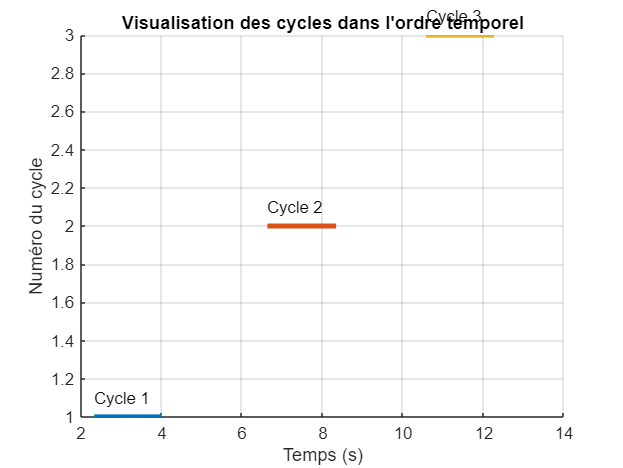

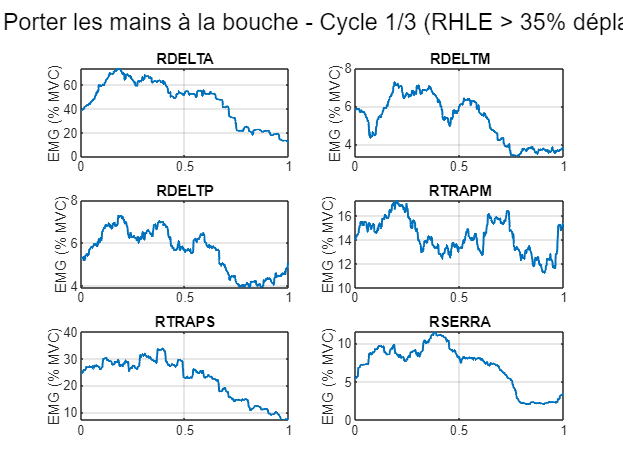

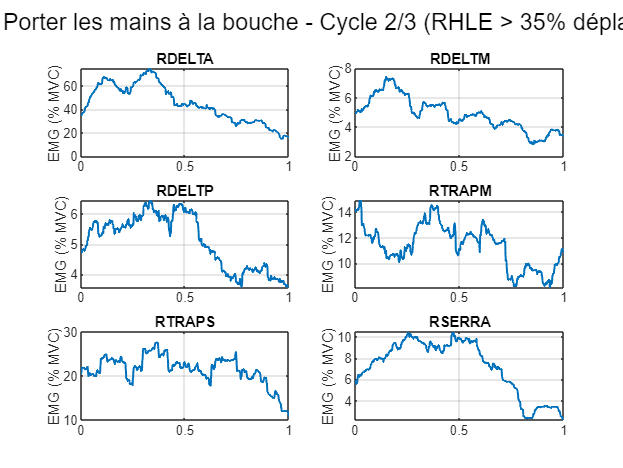

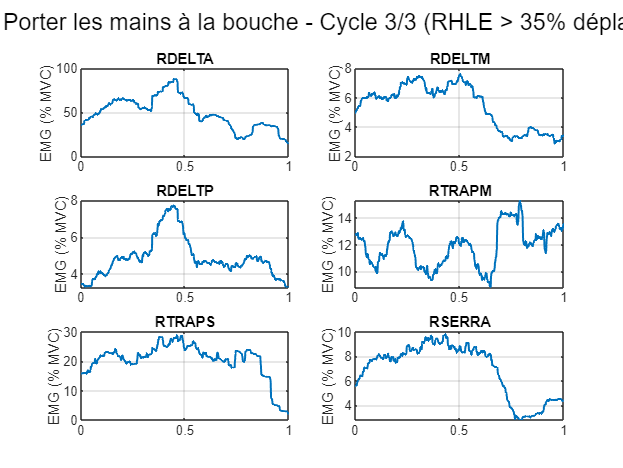

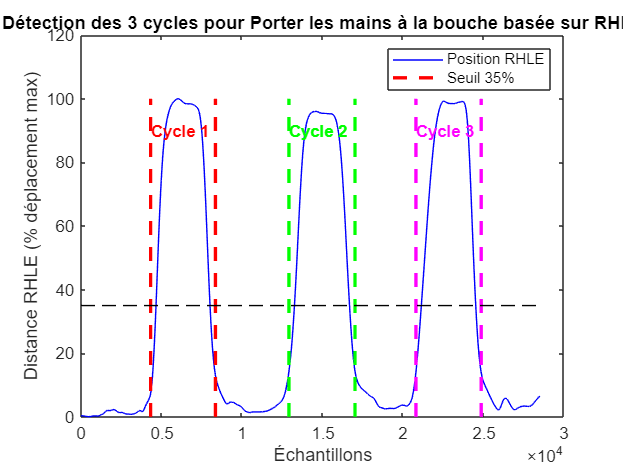

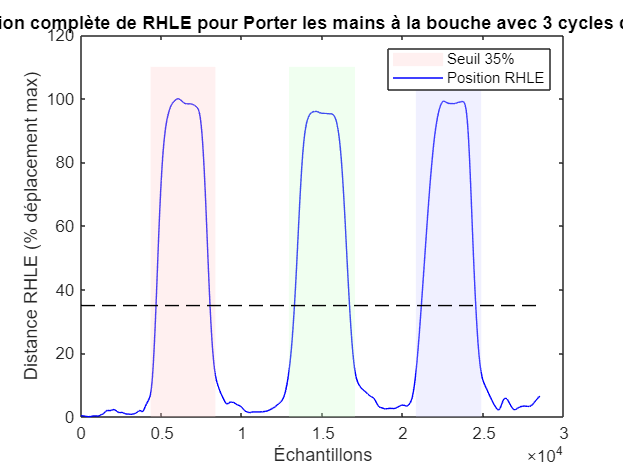

Traitement du mouvement fonctionnel 2: Toucher le haut de la tête
Vérification de l'ordre temporel des cycles :
Cycle 1: Début à 1.89 s, Fin à 3.58 s (Durée: 1.69 s)
Cycle 2: Début à 6.38 s, Fin à 8.87 s (Durée: 2.49 s)
Cycle 3: Début à 11.49 s, Fin à 13.80 s (Durée: 2.31 s)
Confirmation: Les cycles sont dans l'ordre temporel croissant.


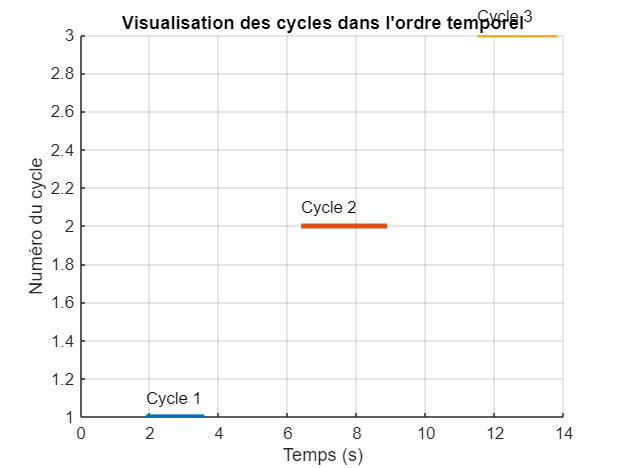

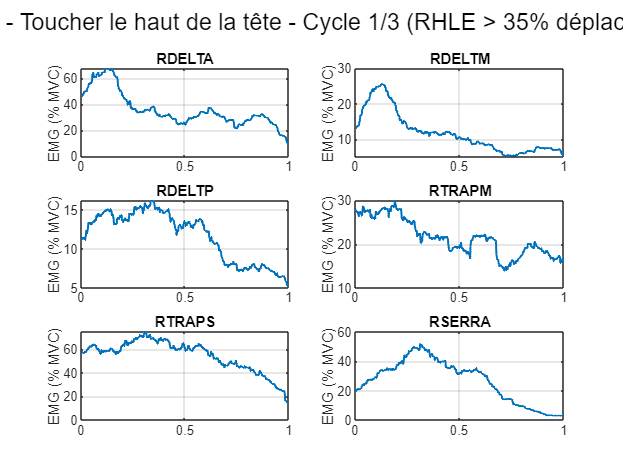

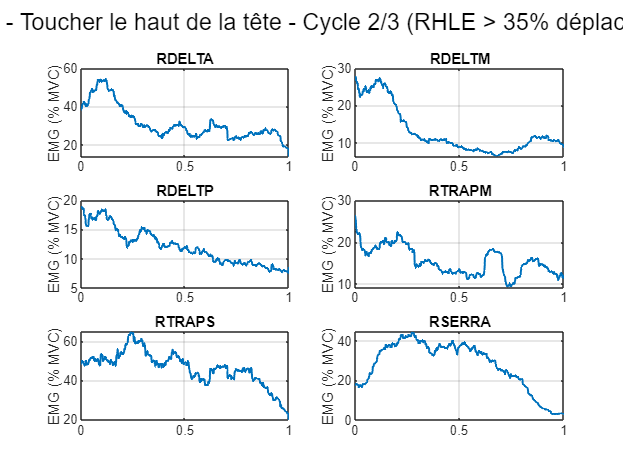

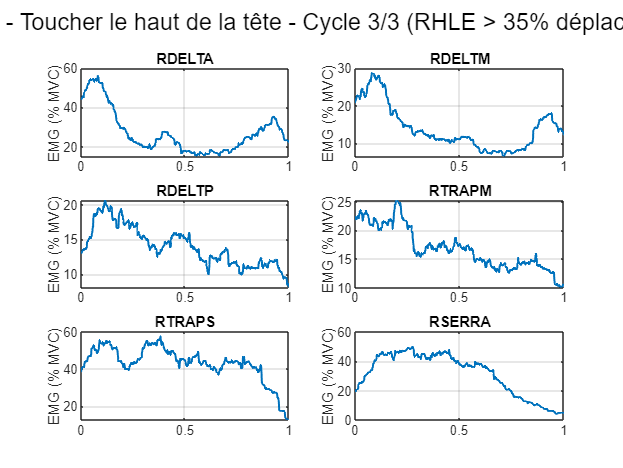

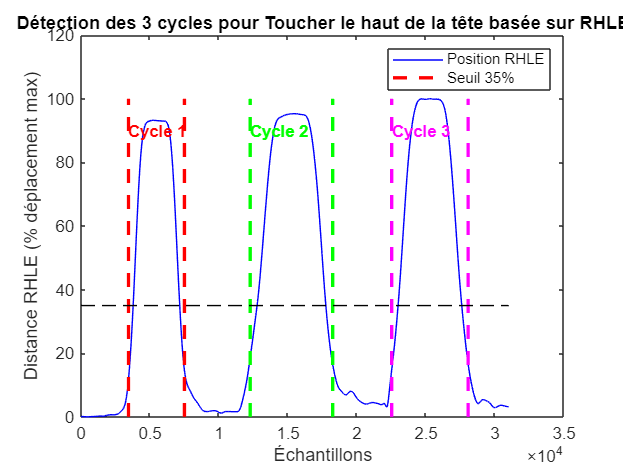

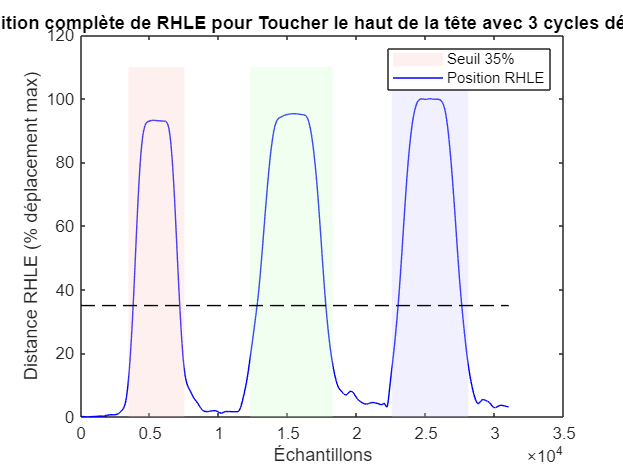

Traitement du mouvement fonctionnel 3: Porter les mains le plus haut possible au-dessus de la tête
Vérification de l'ordre temporel des cycles :
Cycle 1: Début à 9.59 s, Fin à 11.57 s (Durée: 1.98 s)
Cycle 2: Début à 13.78 s, Fin à 16.15 s (Durée: 2.38 s)
Cycle 3: Début à 19.07 s, Fin à 21.21 s (Durée: 2.14 s)
Confirmation: Les cycles sont dans l'ordre temporel croissant.


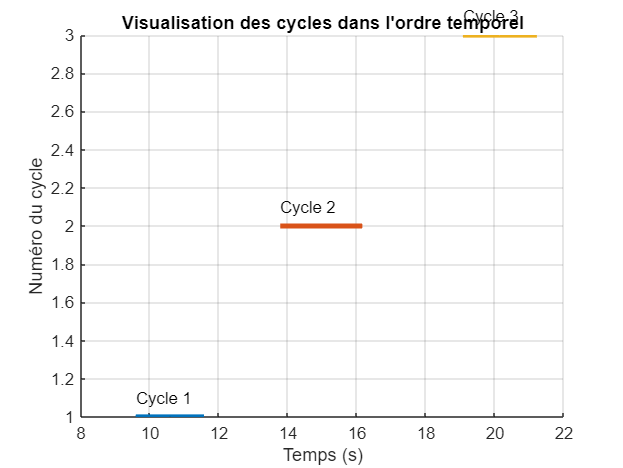

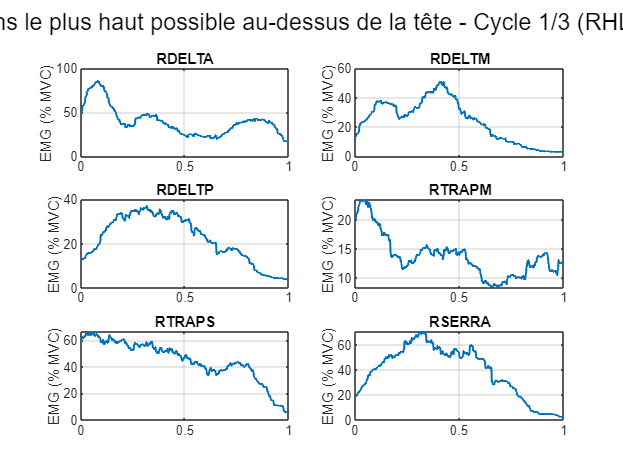

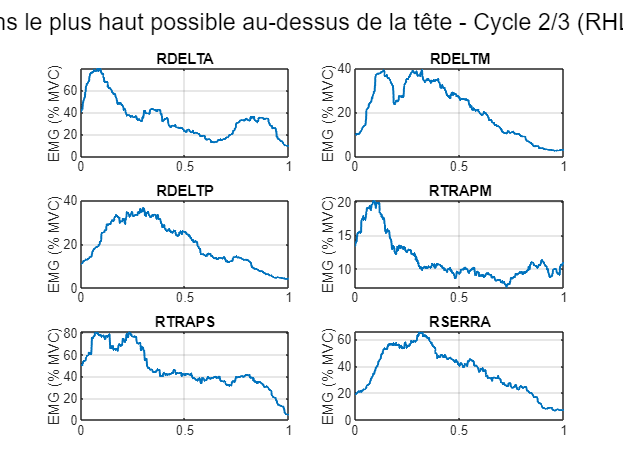

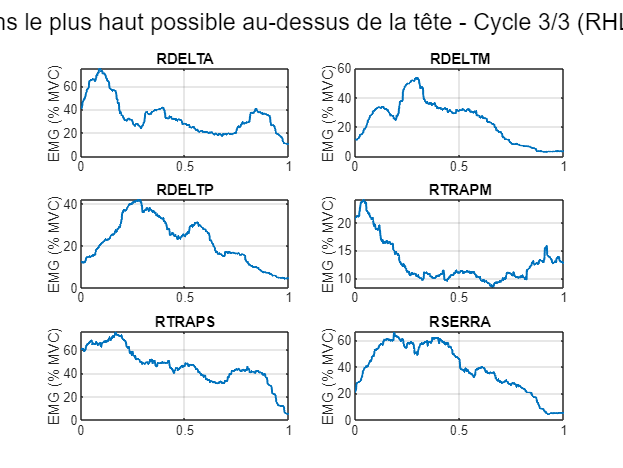

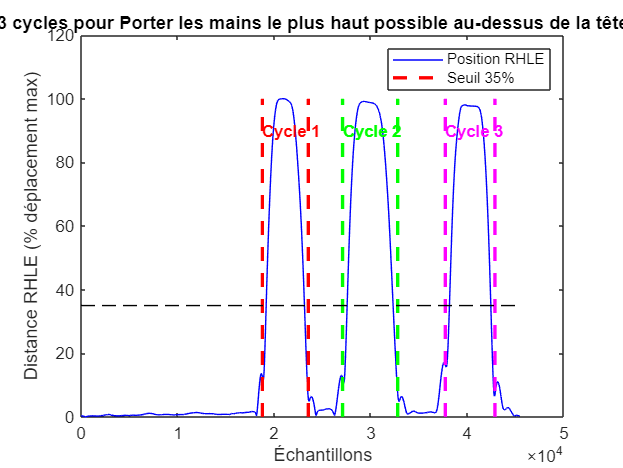

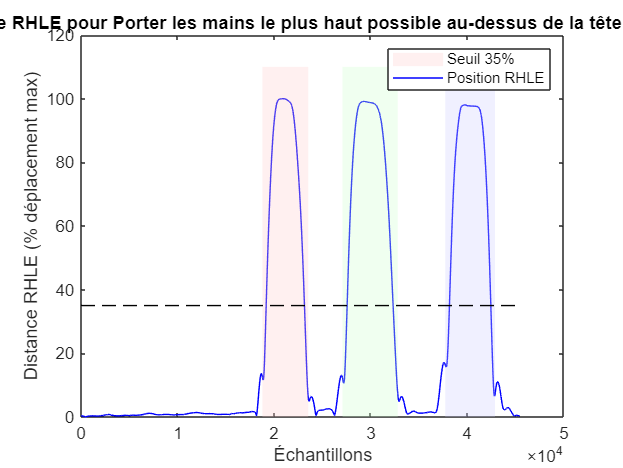

Traitement du mouvement fonctionnel 4: Porter les mains le plus haut possible le long de la colonne vertébrale
Vérification de l'ordre temporel des cycles :
Cycle 1: Début à 1.71 s, Fin à 4.44 s (Durée: 2.73 s)
Cycle 2: Début à 6.19 s, Fin à 8.94 s (Durée: 2.75 s)
Cycle 3: Début à 10.14 s, Fin à 12.59 s (Durée: 2.45 s)
Confirmation: Les cycles sont dans l'ordre temporel croissant.


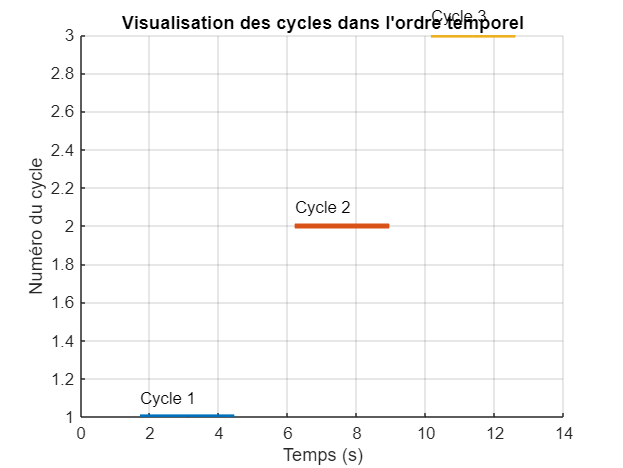

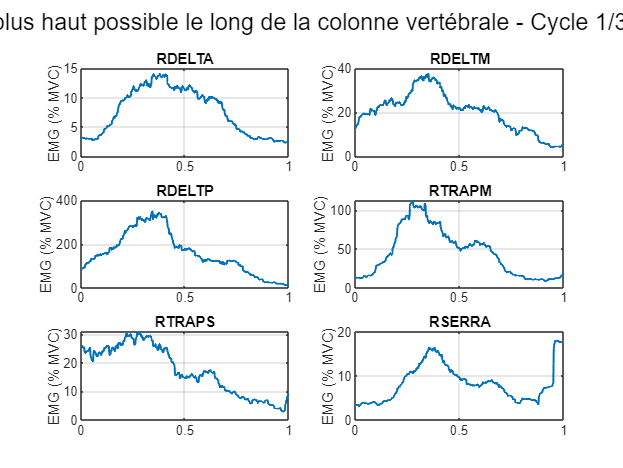

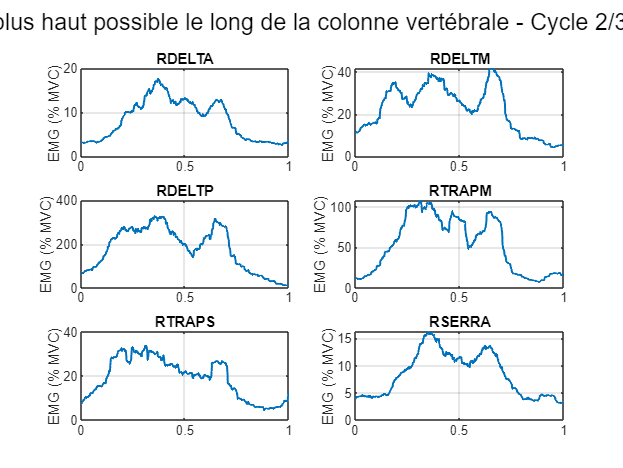

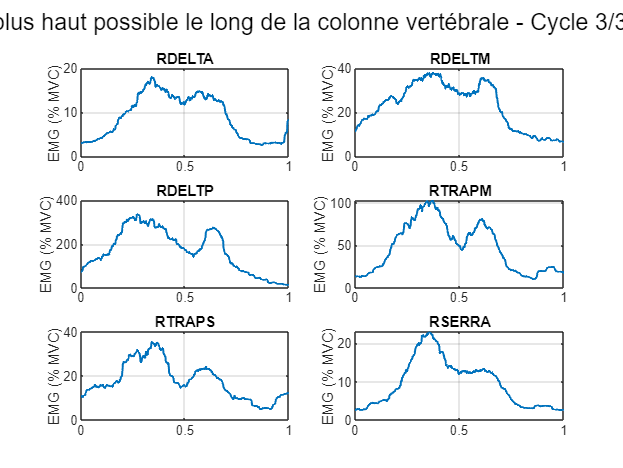

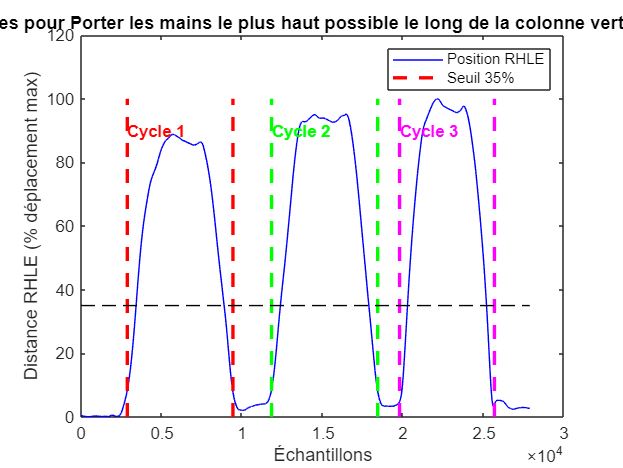

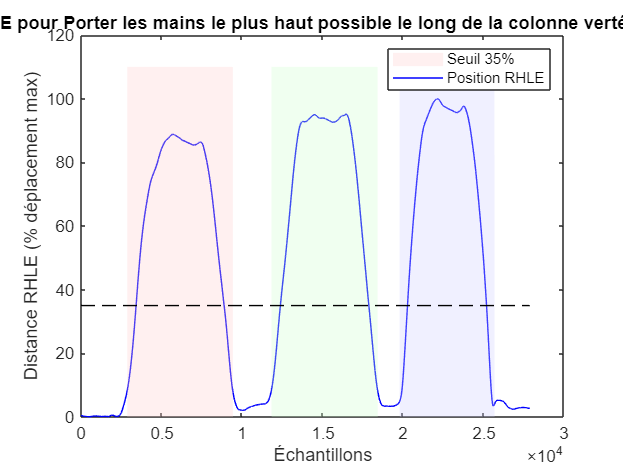

clc, clear all;

% Ajout de la bibliothèque btk
addpath(genpath('C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\btk'));
    
% Définition des paramètres
[subjects, muscles, functional_labels, analytic_labels, assigned_analytics] = defineParameters();
    
% Paramètres EMG et détection de mouvements
[b, a, rms_window, num_points, time_normalized, position_threshold_percent, min_duration, num_cycles] = defineProcessingParameters();
    
% Calcul des MVC
mvc = calculateMVC(subjects, muscles, assigned_analytics, b, a, rms_window);
    
% Traitement des données fonctionnelles
[all_functional_data, num_available_cycles_per_functional] = processFunctionalData(subjects, muscles, functional_labels, b, a, rms_window, num_points, time_normalized, position_threshold_percent, min_duration, num_cycles, mvc);

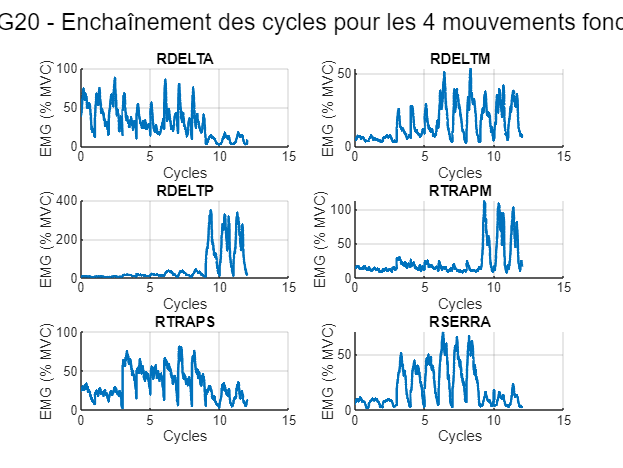

    
% Création des visualisations
visualizeAllFunctionalData(subjects, muscles, functional_labels, all_functional_data, num_available_cycles_per_functional, num_points);

    
% Sauvegarde des données (aller dans la fonction pour mettre la sauvegarde)
saveAllData(subjects, muscles, functional_labels, all_functional_data, num_available_cycles_per_functional, num_points);

Matrice de données créée avec 6 muscles et 12000 points temporels

Récapitulatif des cycles détectés:
-----------------------------
Mouvement 1 - Porter les mains à la bouche: 3 cycles
Mouvement 2 - Toucher le haut de la tête: 3 cycles
Mouvement 3 - Porter les mains le plus haut possible au-dessus de la tête: 3 cycles
Mouvement 4 - Porter les mains le plus haut possible le long de la colonne vertébrale: 3 cycles
Total: 12 cycles
